## Lista 9 - Revisão P3 - Robótica

clear; clc;
import RoboticaBiblioteca.*
printListaManipuladores()

--------------------> Lista de Manipuladores <-----------------------
1 - Manipulador Cartesiano: PPP
   1.1 - Manipulador Pórtico: cartesianos, mas com base em suportes
2 - Manipulador Cilíndrico: RPP
3 - Manipulador Articulados/Antropomórficos: RRR
4 - Manipulador Esféricos/Polares: RRP
5 - Manipulador SCARA: RRP, diferente do esférico, tem três eixos z0,
                       z1 e z2 todos verticais e paralelos


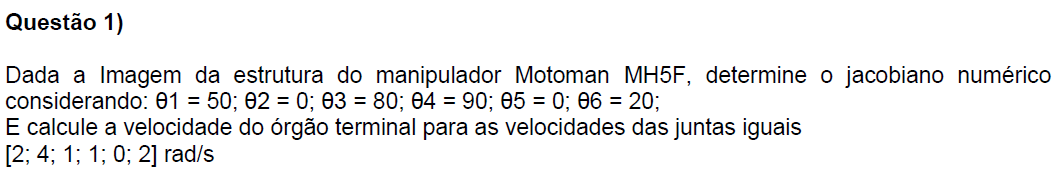

**singularidade theta5 = 0, gimbal lock (software não mostra, mas na pratica sim)**

**para programar na pratica todos os angulos é igual a zero, menos o theta5**

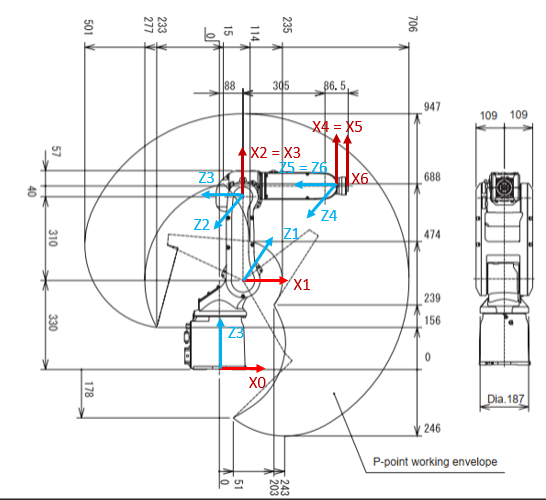

|  link  |   a   | alpha |    d    |      theta       |

| 0 - 1 |  88  |   -90   |  330  |    theta1*     |  R

| 1 - 2 | 310 | +-180 |    0    | theta2* - 90|  R

| 2 - 3 |  40  |   -90   |    0    |    theta3*     |  P

| 3 - 4 |   0   |  +90   | -305  |    theta4*     |  R }

| 4 - 5 |   0   |   -90   |    0    |    theta5*     |  R }  Punho esférico

| 5 - 6 |   0   |     0    |  -80   |    theta6*     |  R }

theta1 = 50;
theta2 = 0;
theta3 = 80;
theta4 = 90;
theta5 = 0;
theta6 = 20;

DH = [88 -90 330 theta1;
      310 180 0 (theta2 - 90);
      40 -90 0 theta3;
      0 +90 -305 theta4;
      0 -90 0 theta5;
      0 0 -80 theta6];
[H06, Alc] = MatProgDenavit(DH)

A01 = 
    0.6428         0   -0.7660   56.5653
    0.7660         0    0.6428   67.4119
         0   -1.0000         0  330.0000
         0         0         0    1.0000

A12 = 
     0    -1     0     0
    -1     0     0  -310
     0     0    -1     0
     0     0     0     1

A23 = 
    0.1736         0   -0.9848    6.9459
    0.9848         0    0.1736   39.3923
         0   -1.0000         0         0
         0         0         0    1.0000

A34 = 
     0     0     1     0
     1     0     0     0
     0     1     0  -305
     0     0     0     1

A45 = 
     1     0     0     0
     0     0     1     0
     0    -1     0     0
     0     0     0     1

A56 = 
    0.9397   -0.3420         0         0
    0.3420    0.9397         0         0
         0         0    1.0000  -80.0000
         0         0         0    1.0000



H06 = 	1.0e+03 *

   -0.0005    0.0009   -0.0001    0.0742
    0.0009    0.0005   -0.0001    0.0884
   -0.0001   -0.0002   -0.0010    1.0261
         0         0         0    0.0010


Alc = 1×6 cell array
    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}


[Velocidade, J] = velJacob(Alc, [2; 4; 1; 1; 0; 2], 'RRRRRR', true)

Z0 = 
     0
     0
     1

O0 = 
     0
     0
     0

Z1 = 
   -0.7660
    0.6428
         0

O1 = 
   56.5653
   67.4119
  330.0000

Z2 = 
    0.7660
   -0.6428
         0

O2 = 
   56.5653
   67.4119
  640.0000

Z3 = 
   -0.1116
   -0.1330
   -0.9848

O3 = 
   31.2444
   37.2357
  646.9459

Z4 = 
   -0.6330
   -0.7544
    0.1736

O4 = 
   65.2882
   77.8074
  947.3123

Z5 = 
   -0.1116
   -0.1330
   -0.9848

O5 = 
   65.2882
   77.8074
  947.3123

O6 = 
   1.0e+03 *

    0.0742
    0.0884
    1.0261



Velocidade = 	1.0e+03 *

    1.3647
    1.9856
   -0.0824
   -0.0026
    0.0015
   -0.0010


J =   -88.4492  447.4425 -248.1783    0.0000  -61.2836    0.0000
   74.2177  533.2412 -295.7674   -0.0000   51.4230   -0.0000
         0  -27.4622   27.4622         0   -0.0000   -0.0000
         0   -0.7660    0.7660   -0.1116   -0.6330   -0.1116
         0    0.6428   -0.6428   -0.1330   -0.7544   -0.1330
    1.0000         0         0   -0.9848    0.1736   -0.9848


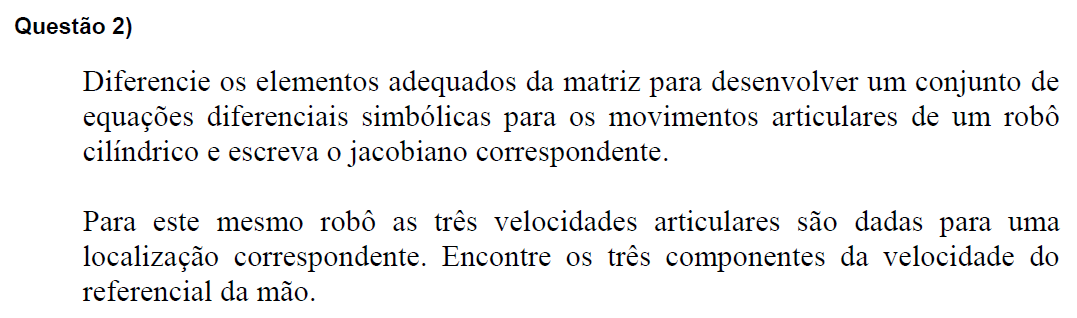

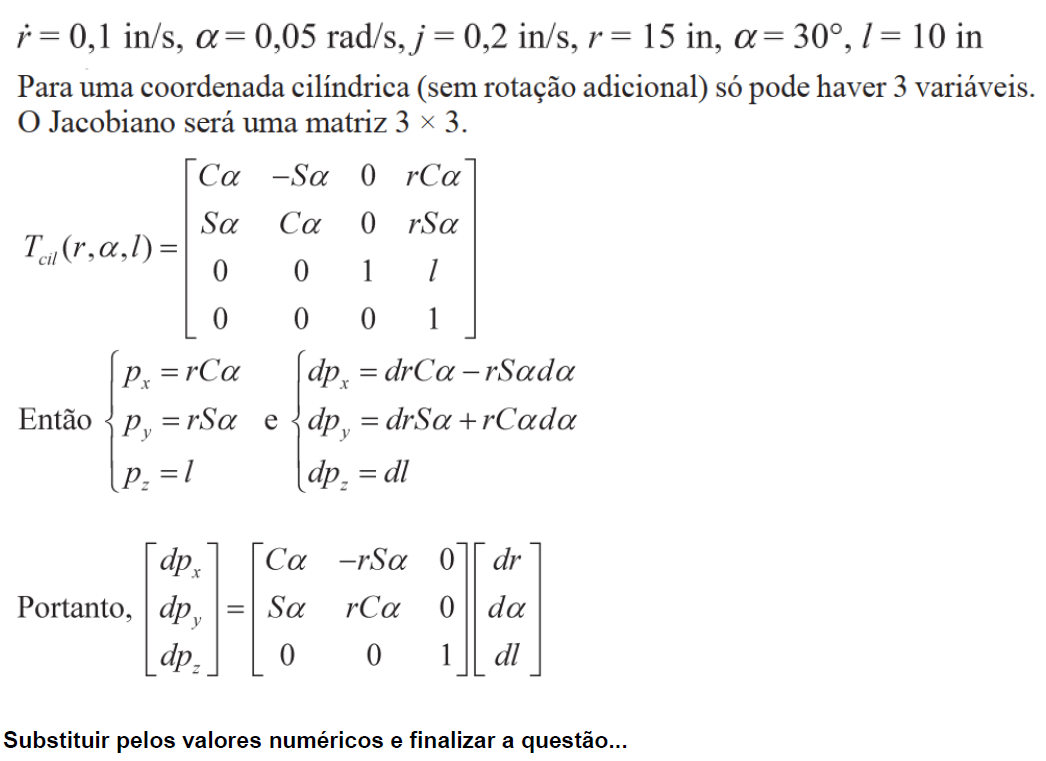

syms r alpha l;
Tcil(r, alpha, l)

$$ans = \left(\begin{array}{cccc} \cos\left(\alpha \right) & -\sin\left(\alpha \right) & 0 & r\,\cos\left(\alpha \right)\\ \sin\left(\alpha \right) & \cos\left(\alpha \right) & 0 & r\,\sin\left(\alpha \right)\\ 0 & 0 & 1 & l\\ 0 & 0 & 0 & 1 \end{array}\right)$$

r = 15;
alpha = 30;
l = 10;
dr = 0.1;
dalpha = 0.05;
dl = 0.2;
dp = [cosd(alpha) -r*sind(alpha) 0; sind(alpha) r*cosd(alpha) 0; 0 0 1] * [dr; dalpha; dl]

dp =    -0.2884
    0.6995
    0.2000


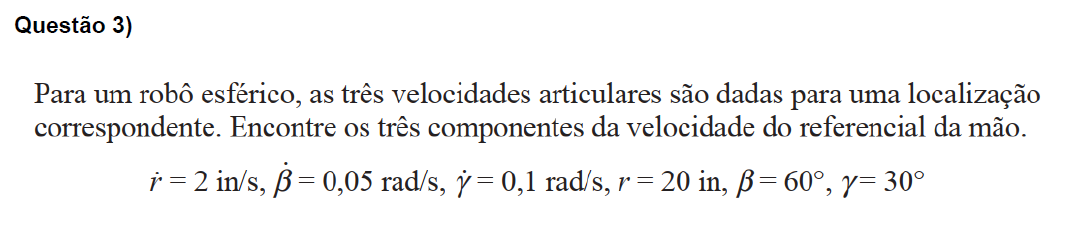

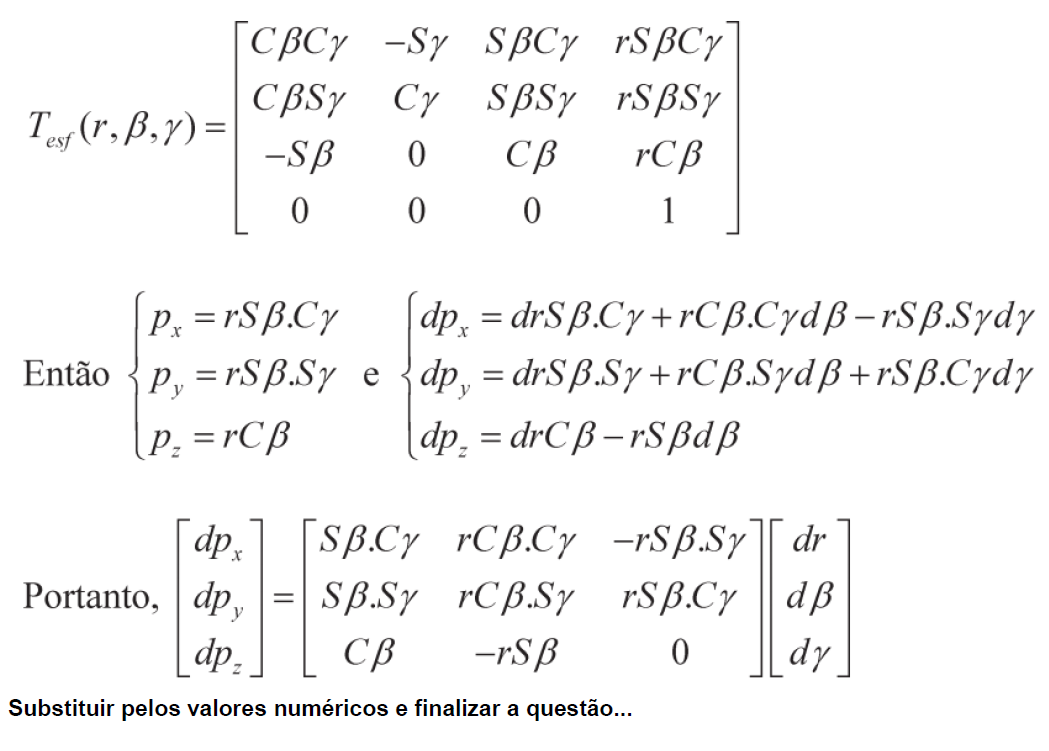

syms r beta gamma;
[R] = Tesf(r, beta, gamma)

$$R = \left(\begin{array}{cccc} \cos\left(\beta \right)\,\cos\left(\gamma \right) & -\sin\left(\gamma \right) & \cos\left(\gamma \right)\,\sin\left(\beta \right) & r\,\cos\left(\gamma \right)\,\sin\left(\beta \right)\\ \cos\left(\beta \right)\,\sin\left(\gamma \right) & \cos\left(\gamma \right) & \sin\left(\beta \right)\,\sin\left(\gamma \right) & r\,\sin\left(\beta \right)\,\sin\left(\gamma \right)\\ -\sin\left(\beta \right) & 0 & \cos\left(\beta \right) & r\,\cos\left(\beta \right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

px = rC(gamma)*S(beta)

py = rS(beta)*S(gamma)

pz = rC(beta)

Fazer derivadas parciais para px, py e pz

dpx = C(gamma)*S(beta)*dr + r*C(gamma)*C(beta)*dbeta - r*S(gamma)*S(beta)*dgamma

dpy = S(beta)*S(gamma)*dr + r*C(beta)*S(gamma)*dbeta + r*S(beta)*C(gamma)*dgamma

dpz = C(beta)*dr - r*S(beta)*dbeta + 0*dgamma

r = 20;
beta = 60;
gamma = 30;
dr = 2;
dbeta = 0.05;
dgamma = 0.1;
M = [cosd(gamma)*sind(beta) r*cosd(gamma)*cosd(beta) -r*sind(gamma)*sind(beta);
     sind(beta)*sind(gamma) r*cosd(beta)*sind(gamma) r*sind(beta)*cosd(gamma);
     cosd(beta) r*sind(beta) 0]

M =     0.7500    8.6603   -8.6603
    0.4330    5.0000   15.0000
    0.5000   17.3205         0


d = [dr; dbeta; dgamma]

d =     2.0000
    0.0500
    0.1000


dp = M*d

dp =     1.0670
    2.6160
    1.8660


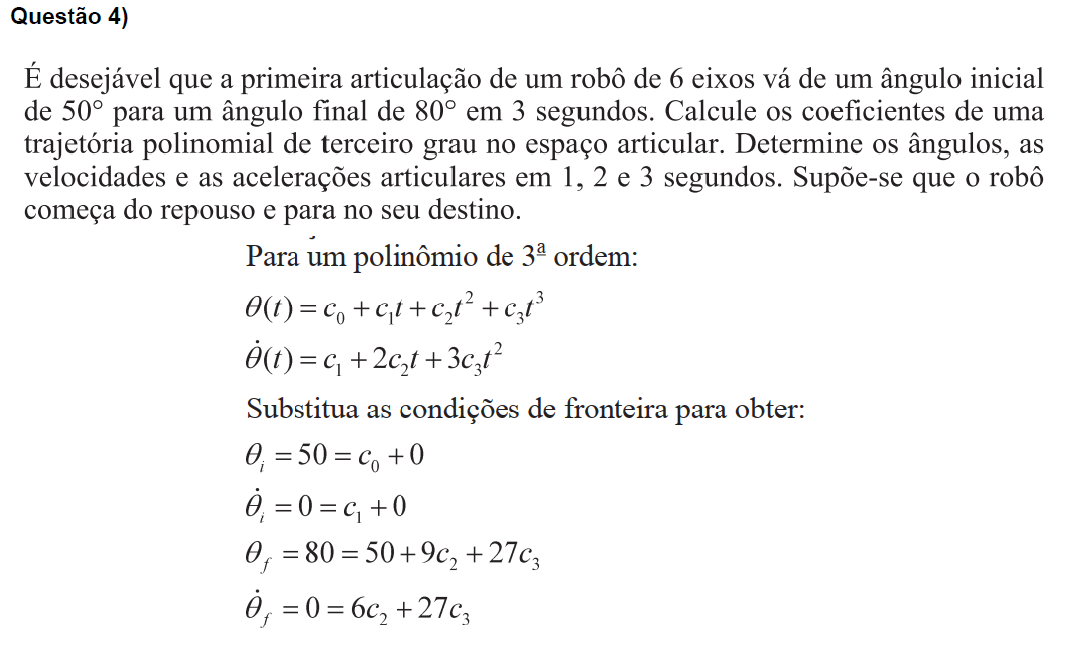

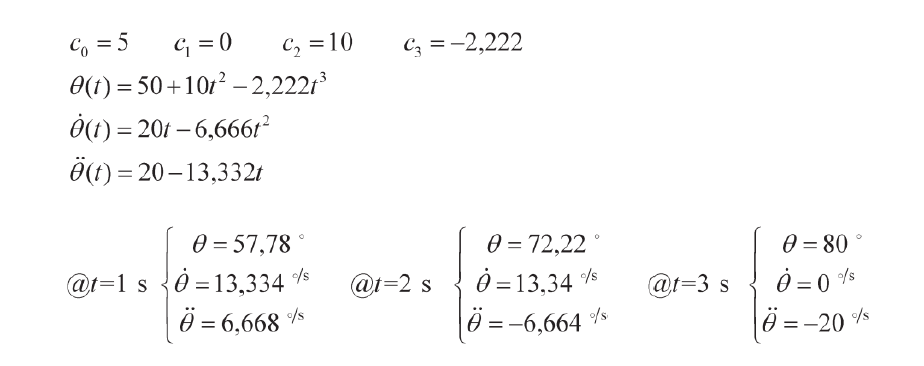

M = coef3(50,80,3)

M =    50.0000
         0
   10.0000
   -2.2222



$$\Theta \left(t\right)=50+10t^2 -2\ldotp 222t^3$$



$$\overset{\cdot }{\theta} \left(t\right)=20t-6\ldotp 666t^2$$



$$\overset{\cdot \cdot }{\theta} \left(t\right)=20-13\ldotp 332t$$


% Para t = 1:
theta = 50 + 10*1^2 - 2.222*1^3

theta = 57.7780

theta_ponto = 20*1 - 6.666*1^2

theta_ponto = 13.3340

theta_2ponto = 20 - 13.332*1

theta_2ponto = 6.6680

% Para t = 2:
theta = 50 + 10*2^2 - 2.222*2^3

theta = 72.2240

theta_ponto = 20*2 - 6.666*2^2

theta_ponto = 13.3360

theta_2ponto = 20 - 13.332*2

theta_2ponto = -6.6640

% Para t = 3:
theta = 50 + 10*3^2 - 2.222*3^3

theta = 80.0060

theta_ponto = 20*3 - 6.666*3^2

theta_ponto = 0.0060

theta_2ponto = 20 - 13.332*3

theta_2ponto = -19.9960

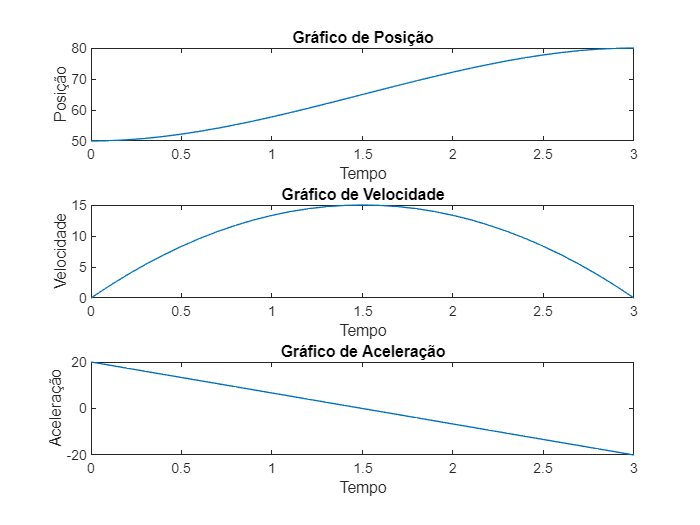

graf3ordPosVelAcel(M,3)

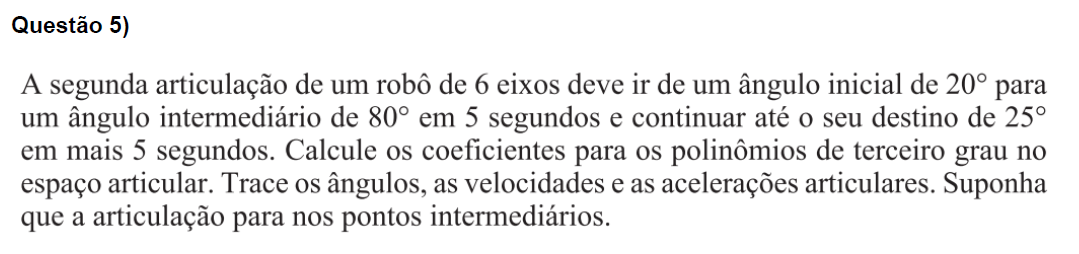

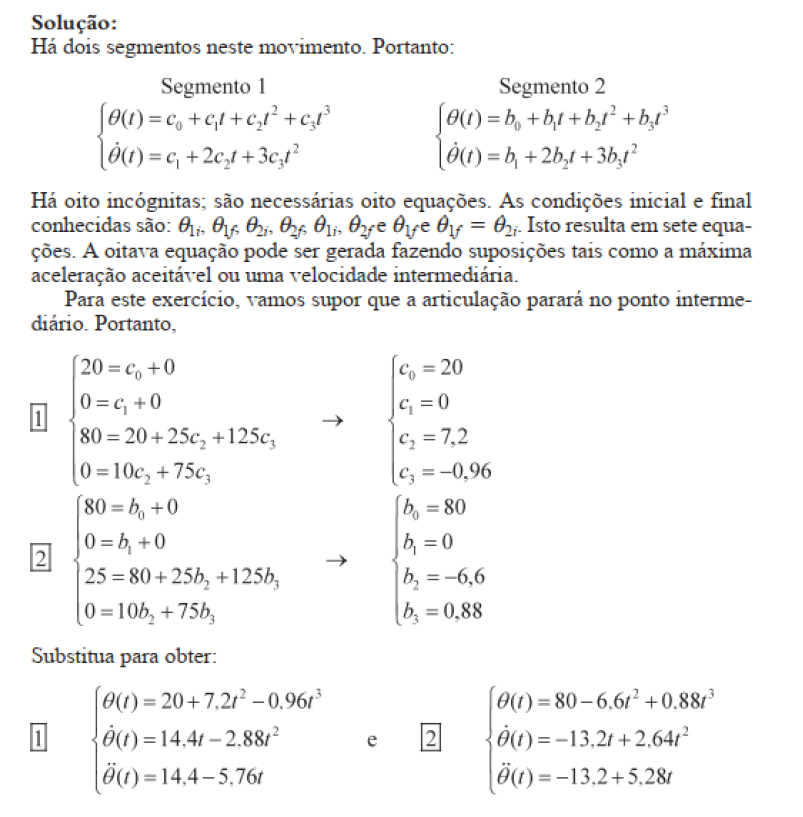

Primeiro Segmento

M1 = coef3(20,80,5)

M1 =    20.0000
   -0.0000
    7.2000
   -0.9600



$$\Theta \left(t\right)=20+7\ldotp 2t^2 -0\ldotp 96t^3$$



$$\overset{\cdot }{\theta} \left(t\right)=14\ldotp 4t-2\ldotp 88t^2$$



$$\overset{\cdot \cdot }{\theta} \left(t\right)=14\ldotp 4-\;5\ldotp 76t$$


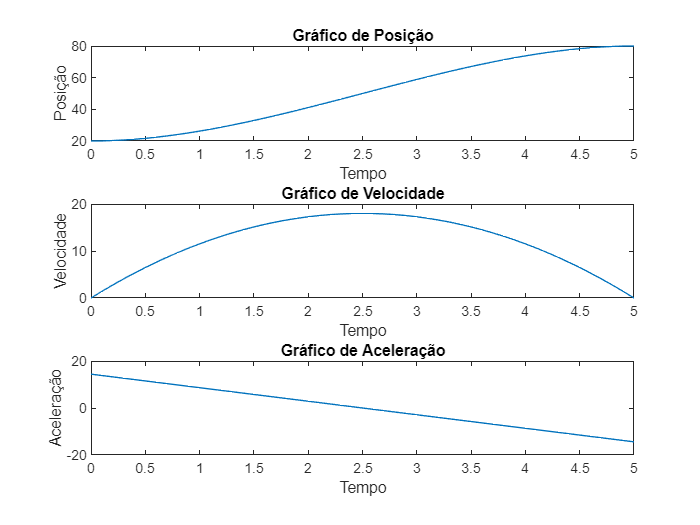

graf3ordPosVelAcel(M1,5)

Segundo Segento

M2 = coef3(80,25,5)

M2 =    80.0000
   -0.0000
   -6.6000
    0.8800



$$\Theta \left(t\right)=80-6\ldotp 6t^2 +0\ldotp 88t^3$$



$$\overset{\cdot }{\theta} \left(t\right)=-13\ldotp 2t+2\ldotp 64t^2$$



$$\overset{\cdot \cdot }{\theta} \left(t\right)=-13\ldotp 2-\;5\ldotp 28t$$


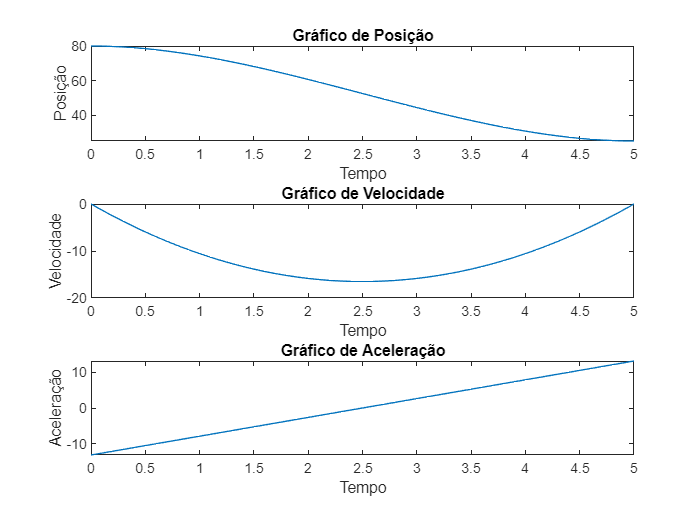

graf3ordPosVelAcel(M2,5)

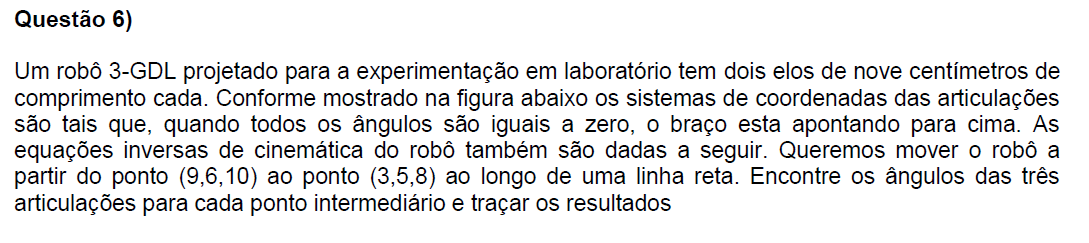

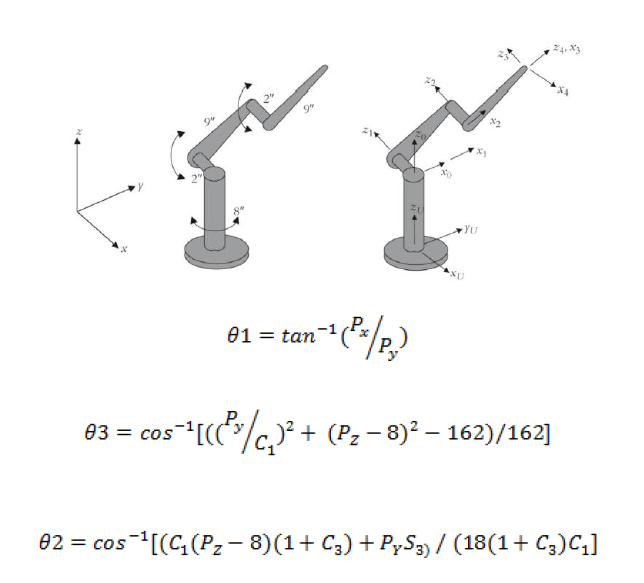

### Como encontrar C1, C2, C3? Descobrir!!!

       Px      Py       Pz                 theta1      theta2   theta3

1     9         6        10                  56.3          

2     8.4      5.9      9.8                54.9

3     7.8      5.8      9.6                52.89

4     7.2      5.7      9.4                51.63

5     6.6      5.6      9.2                49.68

6     6         5.5      9                   47.48

7     5.4      5.4      8.8                45

8     4.8      5.3      8.6                42.16

9     4.2      5.2      8.4                38.92

10   3.6      5.1      8.2                35.21

11   3         5         8                    30.96